# Transverse-shear locking due incompatible discretization spaces

The transverse-shear locking can be attributed to the incompatibility of the discretization space for the vertical displacement and rotation fields. This manifests as residual transverse-shear forces for thin plates which trigger this numerical artifact. More information on this topic you can find [here](matlab:open('../4_TransverseShearLocking_TimoshenkoBeam/main_Chapter4_TransverseShearLocking_TimoshenkoBeam.mlx')) based on the Timoshenko beam problem.

In this section the shear forces $q_x = \alpha G t \gamma_x = \alpha G t \overbrace{\left( \frac{\partial w}{\partial X} + \beta_y \right)}^{\gamma_x}$are computed using both the bilinear and the biquadratic elements along the line $X = 0.5$ m.

Go to [THIS](matlab:open('./main_Chapter4_Locking_ReissnerMindlinCantileverPlate.mlx')) Section in the main driver script *Transverse Shear Locking in Shear-Deformable Plates *`-`* Cantilever Plate Subject to Vertical Distributed Load*

Go to [NEXT](matlab:open('./main_Chapter42_ReissnerMindlinCantileverPlate_SlendernessStudy.mlx')) Section *Slenderness study on transverse shear-locking*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

vars = ["mshQ1" "mshQ2" "numPts" "NQ1" "NQ2" "uQ1" "uQ2" "qxEx" ...
    "propStr" "propNewtonRaphson"];
str = "This mlx-file should be run from parent mlx-file " + ...
    "main_Chapter3_Locking_ReissnerMindlinCantileverPlate.mlx";
for ii = 1:length(vars)
    if ~exist(vars(ii), 'var') 
        error(strcat("Variable ", vars(ii), " is not defined. ", str));
    end
end

## Initialization of the evaluation points along the x-direction where the shear forces are computed

Definition of the vertical deflection $w(\xi,\eta)$, rotation $\beta_x,\beta_y$, position $\mathbf{X}(\xi,\eta)$, jacobian $\mathbf{J} (\xi, \eta)$, the derivative of the vertical deflection with respect to the physical space $\frac{\partial w (\xi,\eta)}{\partial x}, \frac{\partial w (\xi,\eta)}{\partial y}$ and shear force $q_x(\xi, \eta), q_y(\xi, \eta)$ function fields

syms wQ1(xi, eta) wQ2(xi, eta) betaxQ1(xi, eta) betaxQ2(xi, eta) ...
    betayQ1(xi, eta) betayQ2(xi, eta) posVctQ1(xi, eta) ...
    posVctQ2(xi, eta) jacobianMtxQ1(xi, eta) jacobianMtxQ2(xi, eta) ...
    dwdxQ1(xi,eta) dwdxQ2(xi,eta) qxQ1(xi, eta) qxQ2(xi, eta)

Computation of the bounding box of the Finite Element mesh and generate a sequence of sampling points onto which to compute the shear forces

boundingBox = [min(mshQ1.nodes(:, 1)) max(mshQ1.nodes(:, 1)) ...
    min(mshQ1.nodes(:, 2)) max(mshQ1.nodes(:, 2))];
yPts = repmat(mean(boundingBox(3:4)), numPts, 1);
xPts = linspace(boundingBox(1), boundingBox(2), numPts);

In the following array containing the values of the shear forces at each evaluation point, the first column corresponds to the bilinear quadrilateral and the second column to the biquadratic quadrilateral mesh

qxPts = zeros(numPts, 2);

## Loop over all the sampling points where the shear forces are computed

for ii = 1:numPts    

### Obtain the coordinates of the evaluation point

    coordPt = [xPts(ii) yPts(ii)];

### Find the element to which the evaluation point belongs to

 **Hint**

In case the point is found to be in more than one elements, then the first element found can be used for the computation of the shear force

    el = nan;
    for jj = 1:numEl
        in = inpolygon(coordPt(1),coordPt(2), ...
            mshQ1.nodes(mshQ1.elements(jj, :),1), ...
            mshQ1.nodes(mshQ1.elements(jj, :),2));
        if in
            el = jj;
            break;
        end
    end

### Verification of the element's validity containing the current point

 **Hint**

The requested point might not belong to any of the elements in the mesh. In this case revise the coordinates of the evaluation point

    if isnan(el)
        error("The point with coordinates (%d, %d) was found " + ...
            "in no element in the mesh", coordPt(1), coordPt(2));
    end

### Computation of the local coordinates of the node in the element's parametric space

 **Hint**

The Newton-Rapshon method is used in order to obtain the parametric coordinates of the evaluation point in the element where it belongs.

 **Reflect**

Why is it used a Newton-Rapshon method for obtaining the parametric coordinates of the evaluation point in the element where it belongs?

 **Reflect**

Are there alterative methods that can be used to solve this inverse problem? Name of one of them along with its advantages and disadvantages as compared to the Newton-Rapshon method

    [xiEta, ~] = ...
        computePointCoordinatesOnCanonicalBilinearQuadrilateral...
        (coordPt', mshQ1.nodes(mshQ1.elements(el, :), 1:2)', ...
        propNewtonRaphson);

### Verification of the coordinates' validity in the element's parametric space

 **Hint**

The element's parametric space is defined in this case as $(\xi, \eta) \in [-1, 1]^2$

    if xiEta(1, 1) < -1 - eps*1e2 || xiEta(1, 1) > 1 + eps*1e2 || ...
            xiEta(2, 1) < -1 - eps*1e2 || xiEta(2, 1) > 1 + eps*1e2
        error("The point with coordinates (%d, %d) is projected " + ...
            "onto element with id %d into local coordinates (%d, %d)", ...
            coordPt(1), coordPt(2), el, xiEta(1, 1), xiEta(2, 1));
    end

### Setup of the element freedom table for this element using the bilinear quadrilateral mesh

    EFTQ1 = [3*mshQ1.elements(el, :) - 2
             3*mshQ1.elements(el, :) - 1
             3*mshQ1.elements(el, :)];
    EFTQ1 = EFTQ1(:);

### Setup the element freedom table for this element using the biquadratic quadrilateral mesh

    EFTQ2 = [3*mshQ2.elements(el, :) - 2
             3*mshQ2.elements(el, :) - 1
             3*mshQ2.elements(el, :)];
    EFTQ2 = EFTQ2(:);

 **Hint**

How should the DOFs be numbered in the Element Freedom Table (EFT)?

### Setup of the expressions for the vertical deflection and rotation fields for the bilinear quadrilateral element

    wQ1(xi, eta) = NQ1*uQ1(EFTQ1(1:3:end), 1); % w(x, y)
    betaxQ1(xi, eta) = NQ1*uQ1(EFTQ1(2:3:end), 1); % beta_x(x, y)
    betayQ1(xi, eta) = NQ1*uQ1(EFTQ1(3:3:end), 1); % beta_y(x, y)

### Setup of the expressions for the vertical deflection and rotation fields for the biquadratic quadrilateral element

    wQ2(xi, eta) = NQ2*uQ2(EFTQ2(1:3:end), 1); % w(x, y)
    betaxQ2(xi, eta) = NQ2*uQ2(EFTQ2(2:3:end), 1); % beta_x(x, y)
    betayQ2(xi, eta) = NQ2*uQ2(EFTQ2(3:3:end), 1); % beta_y(x, y)

  **Try**

Setup the expressions for the vertical deflection and rotation fields for the bilinear quadrilateral element using selective reduced-integration

 **Reflect**

What do this expressions indicate in this case? Think of spurious energy modes

### Computation of the Jacobian matrix as a function in the element level


$$\left[ \begin{array}{c} X (\xi, \eta) \\ Y (\xi, \eta) \end{array} \right] = \mathbf{X}(\xi, \eta) = \sum_{i=1}^{n}N_i (\xi, \eta) \mathbf{X}_i$$



$$\mathbf{J}(\xi, \eta) = \left[ \begin{array}{cc} \frac{\partial X}{\partial \xi} & \frac{\partial X}{\partial \eta} \\ \frac{\partial Y}{\partial \xi} & \frac{\partial Y}{\partial \eta} \end{array} \right]$$


... for the the bilinear quadrilateral element

    posVctQ1(xi, eta) = NQ1*mshQ1.nodes(mshQ1.elements(el, :), 1:2);
    jacobianMtxQ1(xi, eta) = jacobian(posVctQ1, [xi eta]);

... for the biquadratic quadrilateral element

    posVctQ2(xi, eta) = NQ2*mshQ2.nodes(mshQ2.elements(el, :), 1:2);
    jacobianMtxQ2(xi, eta) = jacobian(posVctQ2, [xi eta]);

### Computation of the derivatives of the vertical deflection with respect to the physical space

 **Hint**

The vertical deflection and the cross-sectional rotation fields of the plate are defined in the parametric space of each element, since they are merely constructed as a linear combination of the basis functions times the Degrees of Freedom (DOFs), namely,


$$w(\xi,\eta) = \sum_{i = 1}^n N_i(\xi, \eta) w_i \\
\beta_x(\xi,\eta) = \sum_{i = 1}^n N_i(\xi, \eta) \beta_{x,i} \\
\beta_y(\xi,\eta) = \sum_{i = 1}^n N_i(\xi, \eta) \beta_{y,i}$$


It is sought to compute the derivatives of the latter quantities with respect to the physical space, namely, $\frac{\partial w}{\partial X}$, $\frac{\partial w}{\partial Y}$, because the computation of the shear forces requires that, namely,


$$q_x (\xi, \eta) = \alpha G t \gamma_x = \alpha G t \overbrace{ \left( \frac{\partial w }{\partial X} + \beta_y \right)}^{\gamma_x} \\
q_y (\xi, \eta) = \alpha G t \gamma_y = \alpha G t \overbrace{ \left( \frac{\partial w }{\partial Y} - \beta_x \right)}^{\gamma_y}$$


To do so, the chain rule can be used, namely, $\frac{\partial w}{\partial \xi} = \frac{\partial w}{\partial X} \frac{\partial X}{\partial \xi} + \frac{\partial w}{\partial Y} \frac{\partial X}{\partial \eta}$. By doing so and then inverting the system for both Cartesian derivatives one obtains the following relation,


$$$\left[ \begin{array}{c} \frac{\partial w}{\partial x} \\ \frac{\partial w}{\partial y} \end{array} \right] = \overbrace{\left[ \begin{array}{cc} \frac{\partial \xi}{\partial x} & \frac{\partial \eta}{\partial x} \\ \frac{\partial \xi}{\partial y} & \frac{\partial \eta}{\partial y} \end{array} \right]}^{\left( \mathbf{J}^{-1} \right)^{\text{T}} = \mathbf{J}^{-\text{T}}} \left[ \begin{array}{c} \frac{\partial w}{\partial \xi} \\ \frac{\partial w}{\partial \eta} \end{array} \right]$$$


where the the inverse of the Jacobian is defined then as follows,


$$\mathbf{J}^{-1}(\xi, \eta) = \left[ \begin{array}{cc} \frac{\partial \xi}{\partial X} & \frac{\partial \xi}{\partial Y} \\ \frac{\partial \eta}{\partial X} & \frac{\partial \eta}{\partial Y} \end{array} \right]$$


Since we are interested in shear force $\gamma_x$, we seek to compute the derivative $\frac{\partial w}{\partial X}$

... corresponding to the bilinear quadrilateral element

    dwdxQ1(xi, eta) = transpose(inv(jacobianMtxQ1(xi, eta)))*...
        [diff(wQ1, xi); diff(wQ1, eta)];

... corresponding to the biquadratic quadrilateral element

    dwdxQ2(xi, eta) = transpose(inv(jacobianMtxQ2(xi, eta)))*...
        [diff(wQ2, xi); diff(wQ2, eta)];

 **Hint**

See how the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html) can be herein nicely leverage to obtain analytical expressions without the need to perform differentiations by hand

  **Try**

Try to change this workflow avoiding overall the use of the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html). Which workflow renders the presentation of numerical methods in engineering more comprehensive?

  **Try**

Compute the analytical expression for the derivative $\frac{\partial w}{\partial X}$ considering the blinear quadrilateral elements with selective reduced-integration

 **Reflect**

What can you say about the analytical expression of the derivative $\frac{\partial w}{\partial X}$ in the case of elements for which selective reduced-integration is used?

### Shear force along the X-direction

The formula for the computation of the shear forces along the X-direction is $q_x (\xi, \eta) = \alpha G t \gamma_x (\xi,\eta) = \alpha G t \overbrace{ \frac{\partial w (\xi,\eta)}{\partial x} + \beta_y(\xi, \eta)}^{\gamma_x(\xi, \eta)}$. The evaluation of this formula for the different element types is provided below

... for the bilinear quadrilateral elements

    qxQ1(xi, eta) = propStr.alpha*propStr.G*propStr.t*([1 0]*...
        dwdxQ1(xi, eta) + betayQ1(xi, eta));
    qxPts(ii, 1) = double(qxQ1(xiEta(1, 1), xiEta(2, 1)));

... for the bilinear quadrilateral elements

    qxQ2(xi, eta) = propStr.alpha*propStr.G*propStr.t*([1 0]*...
        dwdxQ2(xi, eta) + betayQ2(xi, eta));
    qxPts(ii, 2) = double(qxQ2(xiEta(1, 1), xiEta(2, 1)));

  **Try**

Evaluate the shear-forces along the X-direction in the middle of the plate using the selective reduced-integration

end

## Analytical solution in terms of the shear force

qxEx(X) = subs(qxEx, {alphaScf, Gsym, tsym, Lsym, psym, ...
    Esym, Isym, Aqsym}, {propStr.alpha, propStr.G, propStr.t, XLx, ...
    propStr.pBar, propStr.E, YLy*(propStr.t^3)/12, YLy*propStr.t});

## Shear force distribution along the X-direction at the middle of the plate

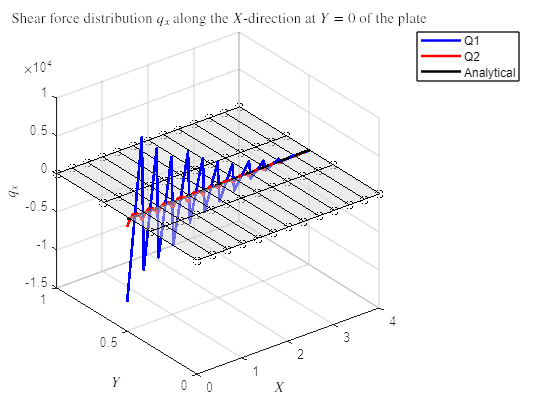

numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshQ1, numVertices, false);
hold on;
plot3(xPts, yPts, qxPts(:, 1), 'b-', 'LineWidth',2);
plot3(xPts, yPts, qxPts(:, 2), 'r-', 'LineWidth',2);
plot3(xPts, yPts, qxEx(xPts), 'k-', 'LineWidth',2);
hold off;
xlabel("$X$", Interpreter="latex")
ylabel("$Y$", Interpreter="latex")
zlabel("$q_x$", Interpreter="latex")
legend("", "", "Q1", "Q2", "Analytical")
title("Shear force distribution $q_x$ along the $X$-direction " + ...
    "at $Y=0$ of the plate", "Interpreter", "latex")

 **Reflect**

How was the analytical solution obtained for this problem? See [here](https://en.wikipedia.org/wiki/Timoshenko%E2%80%93Ehrenfest_beam_theory) for more information on shear-deformable cantilever beams and existing analytical solutions.